# Cooperative MARL for Very Strong Control Loops

## Model

mdl = "DistillationVeryStrongMixed";
open_system(mdl);

## Environment

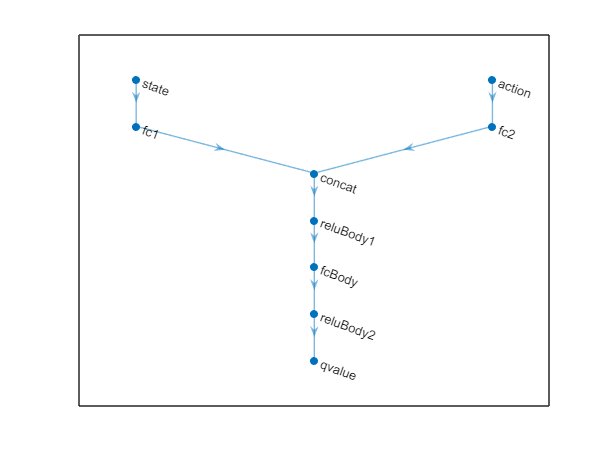

[env,obsInfo,actInfo] = localCreateEnv(mdl);
rng(1);
Ts = 0.1; % Time step
Tf = 250; % End time
agent31 = create31TD3(obsInfo{1}, actInfo{1},Ts);

agent32 = create32TD3(obsInfo{2}, actInfo{2},Ts);

## Training Options

maxepisodes = 250; 
maxsteps = ceil(Tf/Ts);
trainOpts = rlMultiAgentTrainingOptions(...
    "AgentGroups","auto",...
    "LearningStrategy", "decentralized",...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',5, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue',[0 0]);

## Simulate once for sanity check

simOpts = rlSimulationOptions('MaxSteps',maxsteps);
exp = sim(env,[agent31 agent32],simOpts);
s1=sum(exp(1).Reward)

s1 = -976.6584

s2=sum(exp(2).Reward)

s2 = -1.4668e+03

s1 + s2

ans = -2.4434e+03

## Training Agent

train([agent31 agent32],env,trainOpts);
save('MixedVeryStrongagent1.mat','agent31') 
save('MixedVeryStrongagent2.mat','agent32') 

## Model

mdl = "DistillationVeryStrongCoop";
open_system(mdl);

## Environment

[env,obsInfo,actInfo] = localCreateEnv(mdl);
rng(1);
agent31 = create31TD3(obsInfo{1}, actInfo{1},Ts);
agent32 = create32TD3(obsInfo{2}, actInfo{2},Ts);

## Training Options

trainOpts = rlMultiAgentTrainingOptions(...
    "AgentGroups","auto",...
    "LearningStrategy", "decentralized",...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',5, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue',[0 0]); %[0 204]

## Simulate once for sanity check

simOpts = rlSimulationOptions('MaxSteps',maxsteps);
exp = sim(env,[agent31 agent32],simOpts);
sum(exp(1).Reward)

ans = -2.4434e+03

sum(exp(2).Reward)

ans = -2.4434e+03

## Training Agent

train([agent31 agent32],env,trainOpts);
save('CoopVeryStrongagent1.mat','agent31') 
save('CoopVeryStrongagent2.mat','agent32') 